images_dark=loadRAWin3dMatrix_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_dsnu',640,480);
images_50=loadRAWin3dMatrix_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_prnu',640,480);
image_mv=loadRAWin3dMatrix_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_mv',640,480);

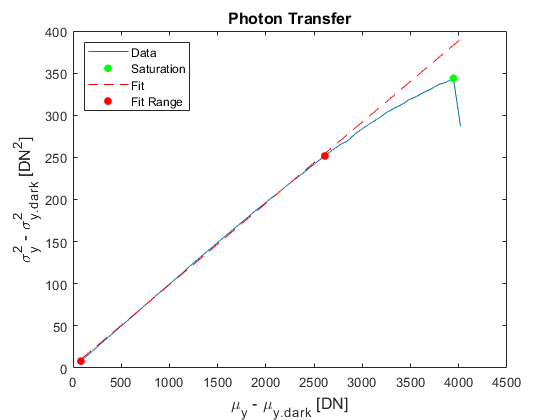

[mean_dark,var_dark,K,pTfigure]=photonTransfer_curve_mono(image_mv);

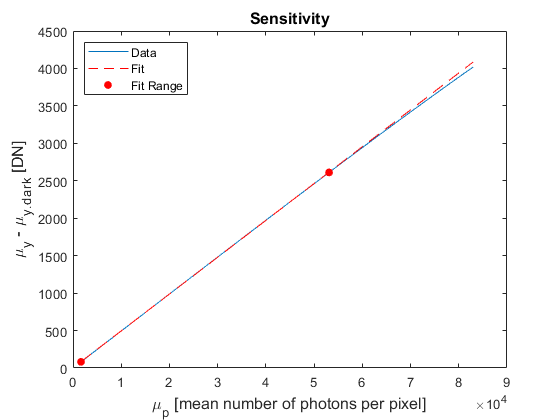

temp_dark_noise=compute_temporaldarknoise(var_dark,(1/12),K);
[R,p_sat,sensfigure]=sensitivity_curve_mono(image_mv,1659.66);

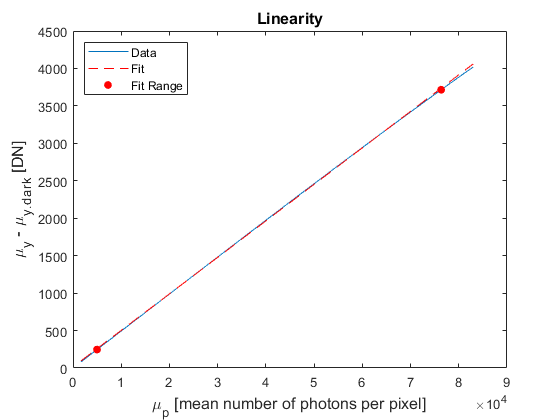

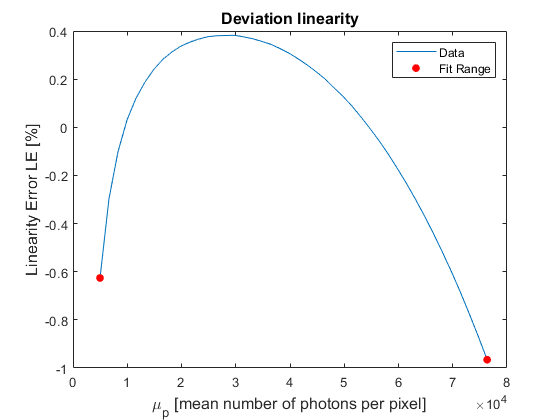

quantum_efficiency=R/K;
[LE_min,LE_max,linfigure,devfigure] = linearity(image_mv,1659.66);

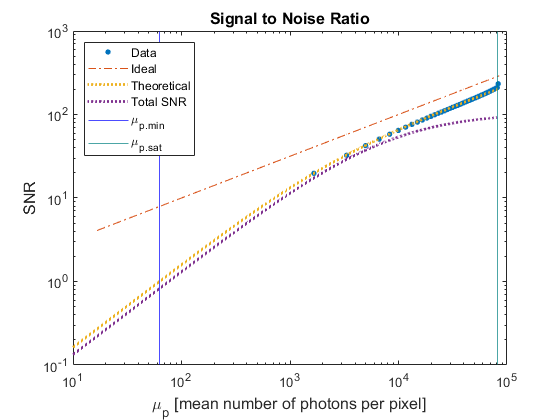

[DSNU,PRNU,sv_50,sv_dark,avg_img_dark,avg_img_50,var_stack_dark,var_stack_50] = DSNU_PRNU(images_dark,images_50,K);
p_min=absolute_sensitivity_threshold(quantum_efficiency,var_dark,K);
e_sat=saturation_capacity(quantum_efficiency,p_sat);
[SNR_max,DR,SNRfig] = plot_SNR(image_mv,1659.66,p_min,p_sat,e_sat,temp_dark_noise,1/12,K,quantum_efficiency,DSNU,PRNU);

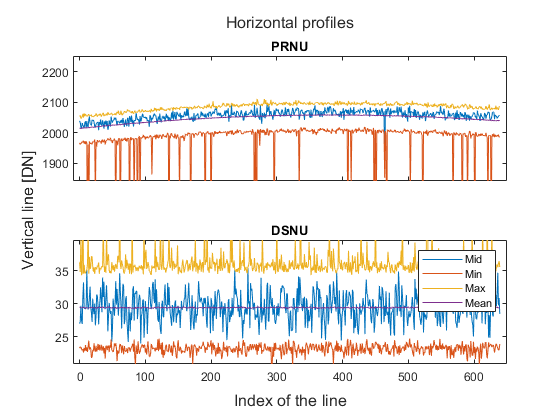

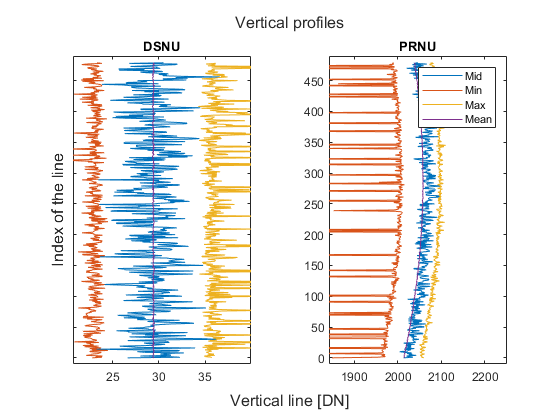

[fig_vertical,fig_horizontal]=profiles(avg_img_dark,avg_img_50);

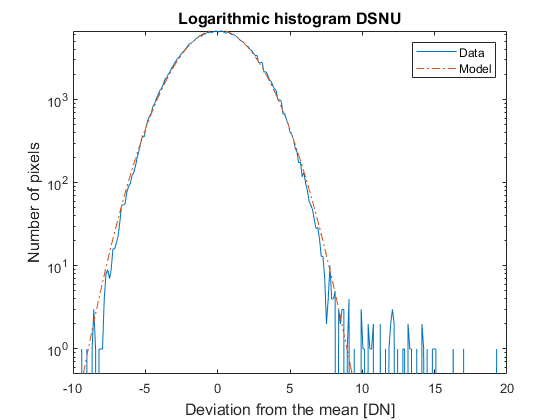

fig_log_hist_DSNU=logarithmic_histogram_DSNU(avg_img_dark,100,sv_dark);

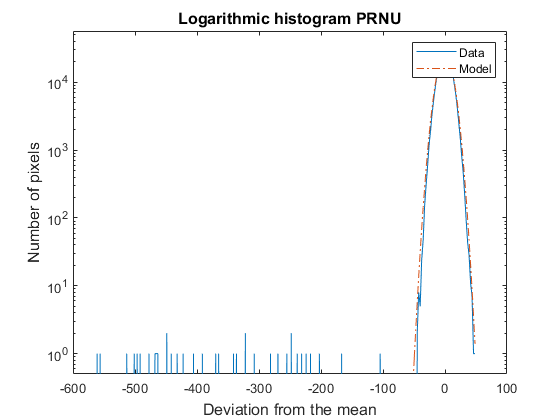

fig_log_hist_PRNU=logarithmic_histogram_PRNU(avg_img_dark,avg_img_50,100);

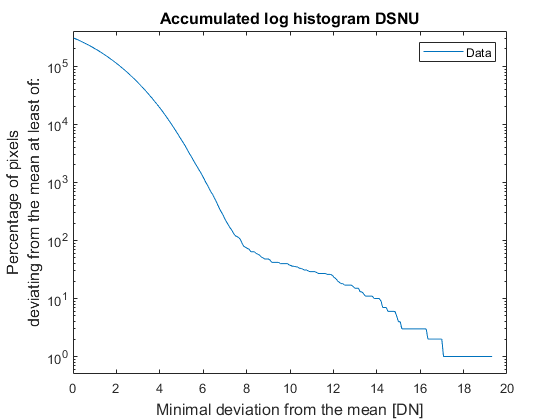

fig_acclog_DSNU=accumulated_log_histogram_DSNU(avg_img_dark,100);

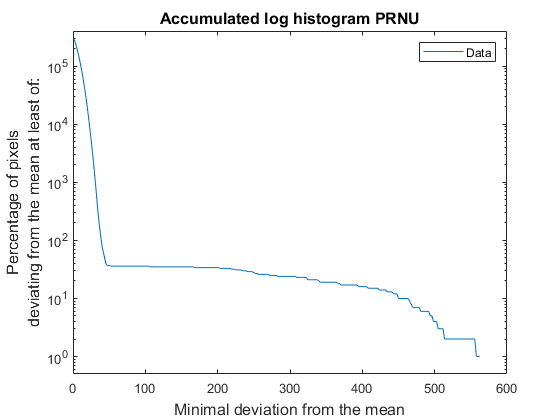

fig_acclog_PRNU=accumulated_log_histogram_PRNU(avg_img_dark,avg_img_50,100);

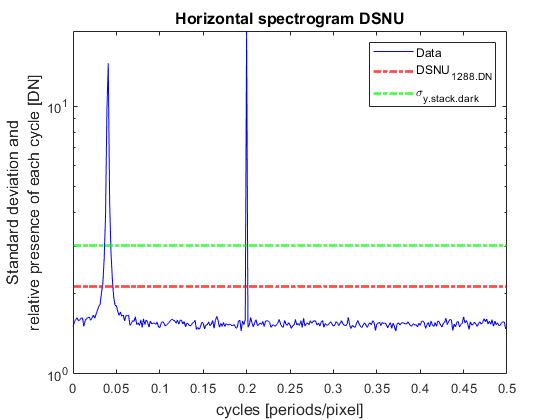

[spatial_var_whitenoise_DSNU_hor,fig_spec_horizontalDSNU] = spectrogram(avg_img_dark,avg_img_50,'horizontal','DSNU',DSNU,var_stack_dark,K);

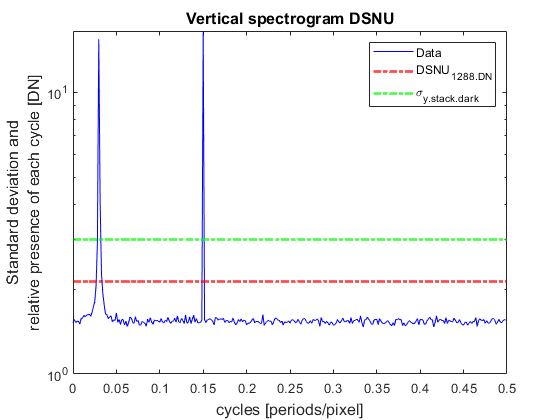

[spatial_var_whitenoise_DSNU_vert,fig_spec_verticalDSNU] = spectrogram(avg_img_dark,avg_img_50,'vertical','DSNU',DSNU,var_stack_dark,K);

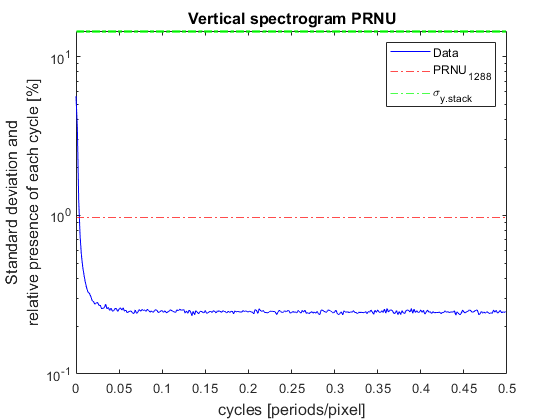

[spatial_var_whitenoise_PRNU_vert,fig_spec_verticalPRNU] = spectrogram(avg_img_dark,avg_img_50,'vertical','PRNU',PRNU,var_stack_50,K);

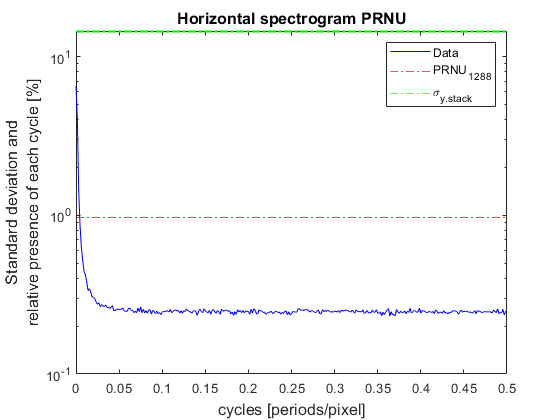

[spatial_var_whitenoise_PRNU_hor,fig_spec_horizontalPRNU] = spectrogram(avg_img_dark,avg_img_50,'horizontal','PRNU',PRNU,var_stack_50,K);

cameraname="simulated camera";
vendor="Simulation";
model="Simulated camera";
datatype="Single";
sensortype="simulated sensor";
diagonal="-";
lenscategory="-";
resolution="640x480";
pixelsize="-";
maximumreadoutrate="-";
gain=0.1;
blacklevel=29.4;
bitdepth=12;
darkcurrentcompensation="-";
interfacetype="-";
lightsource="Integrating sphere";
lightsourcenonuniformity="-";
irradiationcalibrationaccuracy="-";
irradiationmeasurementerror="-";
standardversion="3.1";
illumination="Variable with constant exposure time";
irradiationsteps=50;
time=datestr(clock);
operationpoint="OP1";
wavelength="XXX";
mu_p_min_area="-";
mu_e_min_area="-";
mu_p_sat_area="-";
mu_e_sat_area="-";



import mlreportgen.dom.*;
D=Document('Test','docx','WordReportTemplate.dotx')

D =   Document with properties:

           OutputPath: 'D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\MATLAB\EMVA1288\Funktionen\Test'
          PackageType: 'zipped'
       ForceOverwrite: 1
         StreamOutput: 0
         TitleBarText: ''
          HTMLHeadExt: ''
         TemplatePath: 'WordReportTemplate.dotx'
                 Type: 'DOCX'
        CurrentHoleId: ''
      CurrentHoleType: ''
    CurrentPageLayout: []
           OpenStatus: 'unopened'
               Parent: []
             Children: [1×0 mlreportgen.dom.Node]
                  Tag: 'dom.Document:6'
                   Id: '6'


open(D)

Error using mlreportgen.dom.Document/open
Cannot find template: WordReportTemplate.dotx

docHeaders = D.CurrentDOCXSection.PageHeaders;
docFooters = D.CurrentDOCXSection.PageFooters;
docHead1=docHeaders(1);
docFoot1=docFooters(1);

docHead1.moveToNextHole
append(docHead1,cameraname);

docFoot1.moveToNextHole
append(docFoot1,time);

figHeight="11.11cm";
figWidth="14.28cm";

while ~strcmp(D.CurrentHoleId,'#end#')
    switch D.CurrentHoleId
        case "vendor"
            append(D,vendor);
        case "model"
            append(D,model);
        case "data type"
            append(D,datatype);
        case "sensor type"
            append(D,sensortype);
        case "diagonal"
            append(D,diagonal);
        case "lens category"
            append(D,lenscategory);
        case "resolution"
            append(D,resolution);
        case "pixel size"
            append(D,pixelsize);
        case "maximum readout rate"
            append(D,maximumreadoutrate);
        case "dark current compensation"
            append(D,darkcurrentcompensation);
        case "interface type"
            append(D,interfacetype);
        case "light source"
            append(D,lightsource);
        case "light source non uniformity"
            append(D,lightsourcenonuniformity);
        case "irradiation calibration accuracy"
            append(D,irradiationcalibrationaccuracy);
        case "standard version"
            append(D,standardversion);
        case {"gain","gain op1"}
            append(D,sprintf('%0.2f',gain));
        case {"black level","black level op1"}
            append(D,sprintf('%0.2f',blacklevel));
        case {"bit depth","bit depth op1"}
            append(D,bitdepth);
        case {"illumination","illumination op1"}
            append(D,Text(illumination));
        case {"irradiation steps","irradiation steps op1"}
            append(D,irradiationsteps);
        case {"op_point","op_point op1"}
            append(D,operationpoint);
        case "wavelength"
            append(D,wavelength);
        case "quantum efficiency"
            append(D,sprintf("%0.2f",quantum_efficiency*100));
        case "sigma_d"
            append(D,sprintf("%0.3f",temp_dark_noise));
        case "sigma_y.dark"
            append(D,sprintf("%0.3f",sqrt(var_dark)));
        case "SNR_max"
            append(D,sprintf("%0.2f",SNR_max));
        case "SNR_max dB"
            append(D,sprintf("%0.2f",20*log10(SNR_max)));
        case "SNR_max bit"
            append(D,sprintf("%0.1f",log2(SNR_max)));
        case "SNR_max_-1 percent"
            append(D,sprintf("%0.3f",1/SNR_max*100));
        case "mu_p.min"
            append(D,sprintf("%0.3f",p_min));
        case "mu_e.min"
            append(D,sprintf("%0.3f",p_min*quantum_efficiency));
        case "mu_p.sat"
            append(D,sprintf("%0.0f",p_sat));
        case "mu_e.sat"
            append(D,sprintf("%0.0f",p_sat*quantum_efficiency));
        case "DR"
            append(D,sprintf("%0.0f",DR));
        case "DR dB"
            append(D,sprintf("%0.1f",20*log10(DR)));
        case "DR bit"
            append(D,sprintf("%0.1f",log2(DR)));
        case "DSNU e"
            append(D,sprintf("%0.1f",DSNU));
        case "DSNU DN"
            append(D,sprintf("%0.1f",DSNU*K));
        case "PRNU percent"
            append(D,sprintf("%0.1f",PRNU));
        case "LE_min"
            append(D,sprintf("%0.3f",LE_min));
        case "LE_max"
            append(D,sprintf("%0.3f",LE_max));
        case "photon transfer"
            saveas(pTfigure,'photontransfer.svg');
            plot=Image('photontransfer.svg');
            plot.Height=figHeight;
            plot.Width=figWidth;
            append(D,plot);
        case "signal-to-noise ratio"
            saveas(SNRfig,'snr.svg');
            plot2=Image('snr.svg');
            plot2.Height=figHeight;
            plot2.Width=figWidth;
            append(D,plot2);
        case "sensitivity"
            saveas(sensfigure,'sensitivity.svg');
            plot3=Image('sensitivity.svg');
            plot3.Height=figHeight;
            plot3.Width=figWidth;
            append(D,plot3);
        case "linearity"
            saveas(linfigure,'linearity.svg');
            plot4=Image('linearity.svg');
            plot4.Height=figHeight;
            plot4.Width=figWidth;
            append(D,plot4);
        case "deviation linearity"
            saveas(devfigure,'deviationlinearity.svg')
            plot5=Image('deviationlinearity.svg');
            plot5.Height=figHeight;
            plot5.Width=figWidth;
            append(D,plot5);
        case "horizontal spectrogram prnu"
            saveas(fig_spec_horizontalPRNU,'spectrhorizPRNU.svg');
            plot6=Image('spectrhorizPRNU.svg');
            plot6.Height=figHeight;
            plot6.Width=figWidth;
            append(D,plot6);
        case "horizontal spectrogram dsnu"
            saveas(fig_spec_horizontalDSNU,'spectrhorizDSNU.svg');
            plot7=Image('spectrhorizDSNU.svg');
            plot7.Height=figHeight;
            plot7.Width=figWidth;
            append(D,plot7);
        case "vertical spectrogram prnu"
            saveas(fig_spec_verticalPRNU,'spectrvertPRNU.svg');
            plot8=Image('spectrvertPRNU.svg');
            plot8.Height=figHeight;
            plot8.Width=figWidth;
            append(D,plot8);
        case "vertical spectrogram dsnu"
            saveas(fig_spec_verticalDSNU,'spectrvertDSNU.svg');
            plot9=Image('spectrvertDSNU.svg');
            plot9.Height=figHeight;
            plot9.Width=figWidth;
            append(D,plot9);
        case "log hist dsnu"
            saveas(fig_log_hist_DSNU,'loghistDSNU.svg');
            plot10=Image('loghistDSNU.svg');
            plot10.Height=figHeight;
            plot10.Width=figWidth;
            append(D,plot10);
        case "log hist prnu"
            saveas(fig_log_hist_PRNU,'loghistPRNU.svg');
            plot11=Image('loghistPRNU.svg');
            plot11.Height=figHeight;
            plot11.Width=figWidth;
            append(D,plot11);
        case "acc log hist dsnu"
            saveas(fig_acclog_DSNU,'acclogDSNU.svg');
            plot12=Image('acclogDSNU.svg');
            plot12.Height=figHeight;
            plot12.Width=figWidth;
            append(D,plot12);
        case "acc log hist prnu"
            saveas(fig_acclog_PRNU,'acclogPRNU.svg');
            plot13=Image('acclogPRNU.svg');
            plot13.Height=figHeight;
            plot13.Width=figWidth;
            append(D,plot13);
        case "horizontal profiles"
            saveas(fig_horizontal,'horizontalprofiles.svg');
            plot14=Image('horizontalprofiles.svg');
            plot14.Height=figHeight;
            plot14.Width=figWidth;
            append(D,plot14);
        case "vertical profiles"
            saveas(fig_vertical,'verticalprofiles.svg');
            plot15=Image('verticalprofiles.svg');
            plot15.Height=figHeight;
            plot15.Width=figWidth;
            append(D,plot15);    
    end
    moveToNextHole(D);
end

close(D)
